binファイルの読み込み

filename = '00000075.bin';
bin = ardupilotreader(filename);

binファイルに含まれるすべてのメッセージをmsgに抽出

msg = readMessages(bin);

読み込み時間帯の指定

d1 = duration([0 04 00],'Format','hh:mm:ss.SSSSSS');
d2 = duration([3 10 00],'Format','hh:mm:ss.SSSSSS');


gpsデータの読み込み

gpsMsg = readMessages(bin,'MessageName',{'GPS'},'Time',[d1 d2]);
gpsData = gpsMsg.MsgData{1,1};

gms = gpsData.GMS; %GPSミリ秒
gwk = gpsData.GWk; %GPS週
gtimeUS = gpsData.TimeUS; %GPSメッセージの起動からのデータ時刻


gpsデータからUTC時刻を生成　

gpsEpoch = datetime(1980,1,6,0,0,0);
gpsseconds = gms + gwk*7*24*3600;
tgps=gpsEpoch+gpsseconds/(24*3600);
tgps.Format = 'yyyy-MM-dd HH:mm:ss.SSSSSS';

tGPS0 = tgps(1); %gps時刻の先頭時刻
gtimeUS0 = gtimeUS(1); %gpeメッセージtimeUSの先頭時間

姿勢データの読込み

attMsg = readMessages(bin,'MessageName',{'ATT'},'Time',[d1 d2]);
attData = attMsg.MsgData{1,1};

atttimeUS = attData.TimeUS; %ATTメッセージデータの起動からのデータ時刻
roll = attData.Roll; %ロールデータ
pitch = attData.Pitch; % ピッチデータ
yaw = attData.Yaw; %ヨーデータ

姿勢データtimeUSに対応するgps時刻生成

attGPS = tGPS0 - gtimeUS0 + atttimeUS;

生成したATTgps時刻＋ATT姿勢データをCSVファイルとして書き込む

t = table(attGPS,roll,pitch,yaw,'VariableNames', {'GPSTime','Roll','Picth','Yaw'});

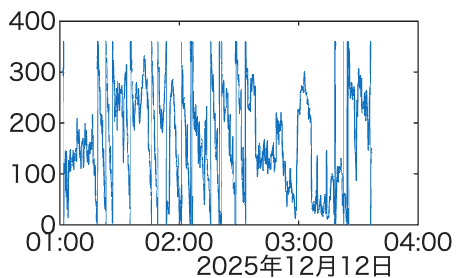

plot(t.GPSTime,t.Yaw);

rcouMsg = readMessages(bin,'MessageName',{'RCOU'},'Time',[d1 d2]);
rcouData = rcouMsg.MsgData{1,1};

rcoutimeUS = rcouData.TimeUS;
rcouGPS = tGPS0 - gtimeUS0 + rcoutimeUS;

moter1 = rcouData.C1;
moter2 = rcouData.C2;
moter3 = rcouData.C3;
moter4 = rcouData.C4;

moter4 =         1500
        1500
        1500
        1500
        1500
        1500
        1500
        1500
        1500
        1500
        1500
        1500
        1500
        1500
        1500


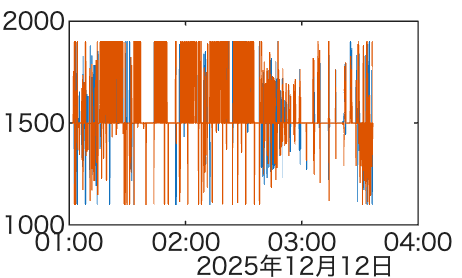

thrustLeft = rcouData.C5;
thrustRight = rcouData.C6;

t2 = table(rcouGPS,moter1,moter2,moter3,moter4,thrustLeft, thrustRight,'VariableNames', {'GPSTime','moter1','moter2','moter3','moter4','thrustLeft','thrustRight'});

plot(t2.GPSTime,t2.thrustLeft); hold on
plot(t2.GPSTime,t2.thrustRight); 


[filepath, name, ext] = fileparts(filename);

attname = strcat(name,"att.xlsx");
new_attfilename = fullfile(filepath, attname);
writetable(t,new_attfilename);

rcouname = strcat(name,"rcou.xlsx");
new_rcoufilename = fullfile(filepath, rcouname);
writetable(t2,new_rcoufilename);
